# Side-By-Side Figures

This example shows how to arrange figures side-by-side on a page.

The example places each figure in adjacent entries of an invisible table, which is a table with no borders or colors. The invisible table causes the inserted figures to appear to be side-by-side.

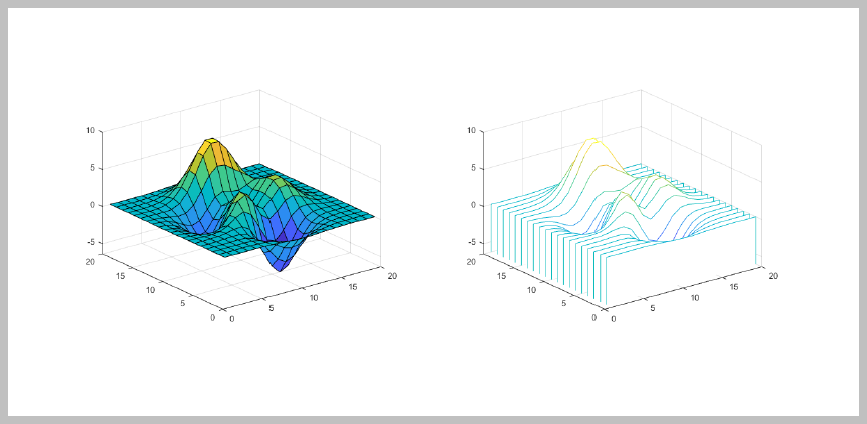

Import the DOM and Report API packages so you do not have to use long, fully-qualified class names. Also, create a Report object.

import mlreportgen.dom.*
import mlreportgen.report.*

% To create a Word report, change the output type from "pdf" to "docx". 
% To create an HTML report, change "pdf” to “html” or "html-file" for a 
% multifile or single-file report, respectively.
rpt = Report('myreport', 'pdf');

Create Figure objects for surface (fig1) and waterfall (fig2) plots. Then, create Image objects wrapped around the figure snapshot image files. Scale the images to fit the table entries created below.

imgStyle = {ScaleToFit(true)};

fig1 = Figure(surf(peaks(20)));
fig1Img = Image(getSnapshotImage(fig1, rpt));
fig1Img.Style = imgStyle;
delete(gcf);

fig2 = Figure(waterfall(peaks(20)));
fig2Img = Image(getSnapshotImage(fig2, rpt));
fig2Img.Style = imgStyle;
delete(gcf);

Insert the images in the only row of a 1x3, invisible layout table (lo_table). A table is considered invisible when the borders are not defined for the table and all of its table entries.

lo_table = Table({fig1Img, ' ', fig2Img});

The images will be sized to fit the table entries only if the table entries' height and width are specified.

lo_table.entry(1,1).Style = {Width('3.2in'), Height('3in')};
lo_table.entry(1,2).Style = {Width('.2in'), Height('3in')};
lo_table.entry(1,3).Style = {Width('3.2in'), Height('3in')};

Set the table width so it spans the width of the page between the margins. Set ResizeToFitContents to false so the table columns are not resized and instead the specified widths are used.

lo_table.Style = {Width('100%'), ResizeToFitContents(false)};

Generate and display the report.

add(rpt, lo_table);
close(rpt);
rptview(rpt);

*Copyright 2018 The MathWorks, Inc.*